# Local Histogram Equilization

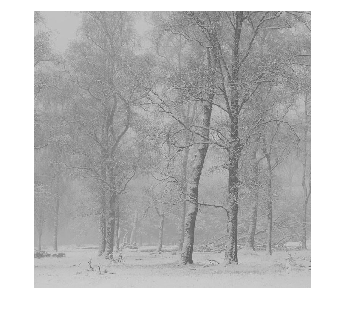

% defining the necessary constants and importing the images
w_r_n = 71;
w_c_n = 71; % means window row numbers and column numbers(size of window)
center_to_end_vertical = (w_r_n - 1)/2;
center_to_end_horizontal = (w_c_n - 1)/2;
im = imread('LC2.jpg');
imshow(im);

im = double(im);
[rnum, cnum] = size(im);

### Normalised Histogram's Weight Calculating Function

%Function that would return normalized histogram density values, given a list containing Intensity values
function [norm_intensity_density] = norm_hist_density_calculator(intensity_list)
    list_size = size(intensity_list);
    num_elements = list_size(2);
    unnorm_intensity_density = zeros(1,256); % contains how frequent each intensity occurs
    for i =1:num_elements
        intensity_value = intensity_list(i)+1;
        unnorm_intensity_density(intensity_value) = unnorm_intensity_density(intensity_value) + 1; 
    norm_intensity_density = unnorm_intensity_density/num_elements;
    end
end

### Implementing Local Histogram Equilization

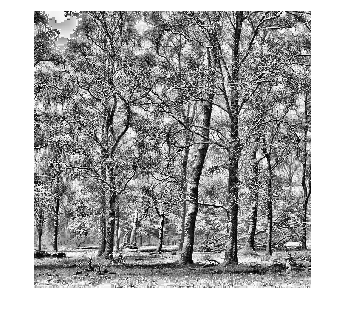

mod_im = zeros(rnum, cnum);
for i = 1:rnum
    for j = 1:cnum
        intensity_value_ij = im(i,j);
        x_top = max(1, i - center_to_end_vertical);
        x_bottom = min(i + center_to_end_vertical, rnum);
        y_left = max(1, j-center_to_end_horizontal);
        y_right = min(cnum, j+center_to_end_horizontal);
        sliced_array = im(x_top: x_bottom, y_left: y_right);
        available_intensity = sliced_array(:)';
        norm_int_dens = norm_hist_density_calculator(available_intensity);
        cdf_value = sum(norm_int_dens(1:intensity_value_ij+1));
        modified_instensity = cdf_value*255;
        mod_im(i, j) = round(modified_instensity);
    end
end
mod_im = uint8(mod_im);
imshow(mod_im);

imwrite(mod_im, 'LC2_window_size71_71_vector.jpg');

intensity_value_ij = 152

x_top = 1

x_bottom = 45

y_left = 1

y_right = 45

sliced_array =    169   183   168   149   155   157   152   160   171   168   170   173   168   164   174   189   193   197   197   194   193   195   195   192   193   192   192   192   192   193   194   195   194   194   194   194   194   194   194   194   194   194   194   194   194
   174   184   173   162   169   169   167   177   164   168   173   171   162   159   168   182   192   193   191   189   191   195   194   189   193   192   192   192   192   193   194   195   194   194   194   194   194   194   194   194   194   194   194   194   194
   181   183   174   168   170   162   158   168   160   172   181   175   164   162   169   175   195   196   194   192   194   198   195   189   193   192   192   192   192   193   194   195   194   194   194   194   194   194   194   194   194   194   194   194   194
   189   184   178   177   171   157   152   160   159   175   185   181   176   178   177   171   188   194   197   196   195   195   193   188   193   192   192   192   1

available_intensity =    169   174   181   189   197   198   188   175   162   178   183   180   179   171   172   187   179   150   136   143   154   165   163   145   161   169   160   160   147   127   145   165   192   192   186   186   195   196   190   188   191   191   191   190   190   183   184   183   184   188


norm_int_dens =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


cdf_value = 0.0247

modified_instensity = 6.2963